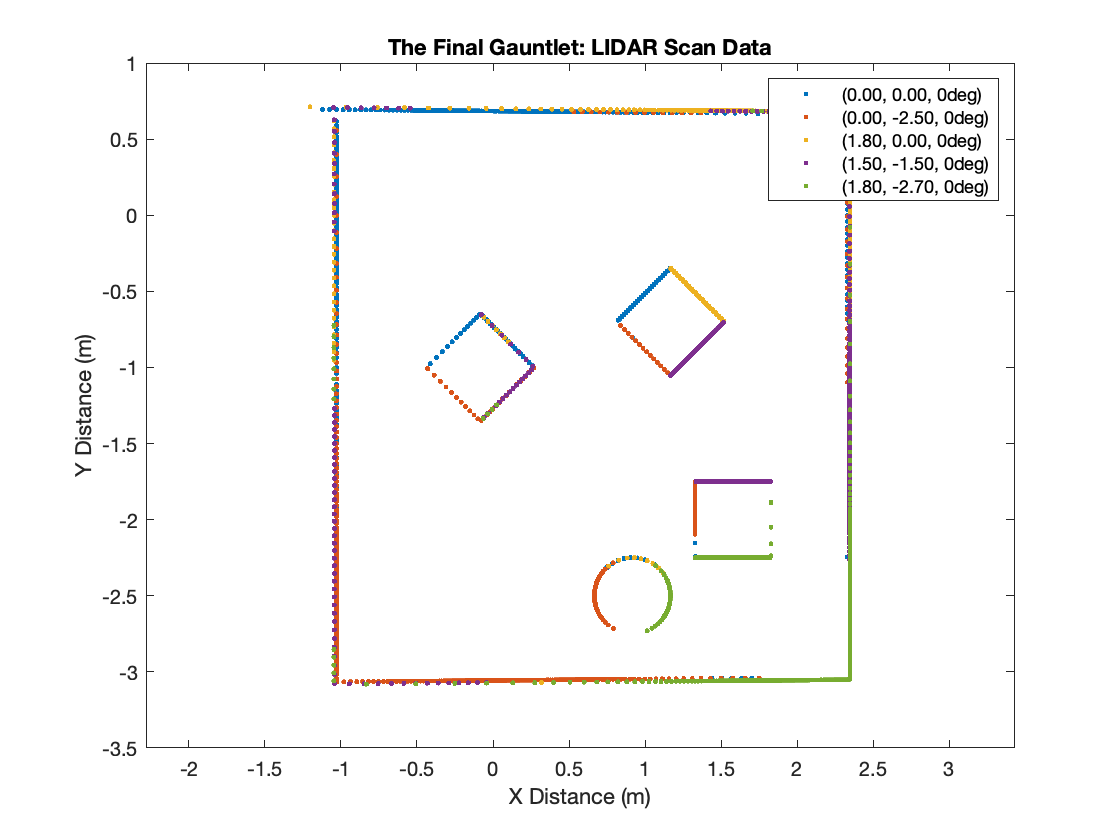

load('scans/lidar2.mat', 'lidar_results', 'lidar_positions');
% lidar.mat has a lidar matrix which is n x 2 x m, where each (:, :, m) is
% one scan in the form of [r, theta], where r and theta are column vectors.
% It also has a 3 x m matrix of column vectors of the format [x, y, phi]

generate_potential_field(x, y, [x1, y1; x2, y1])

clf;

for i=1:size(lidar_results, 3)
    r_G = to_global(lidar_results(:, 1, i), lidar_results(:, 2, i), lidar_positions(i, 1:2), lidar_positions(i, 3));
    
    label = sprintf("(%1.2f, %1.2f, %1.0fdeg)", lidar_positions(i, 1), lidar_positions(i, 2), lidar_positions(i, 3));
        
    plot(r_G(:, 1), r_G(:, 2), '.', 'DisplayName', label); hold on;
end

legend show;
title("The Final Gauntlet");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
xlim([-1.5, 3]);
ylim([-3.5, 1]);

axis equal;

hold off;

## Potential Field

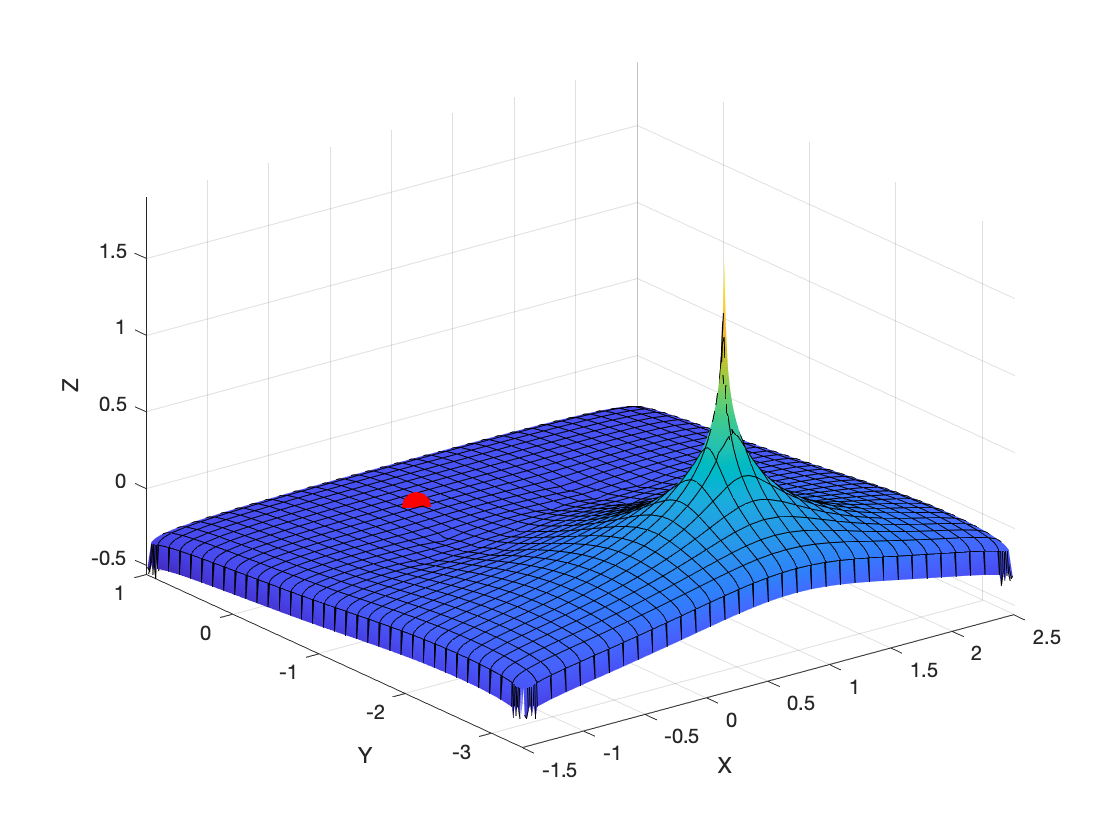

% [X, Y] = meshgrid(linspace(-5, 5), linspace(-5, 5));

[f, Z] = gauntletPotentialField();
figure(2); clf;
fsurf(f, [-1.5, 2.5, -3.37, 1]); xlim([-1.5, 2.5]); ylim([-3.37, 1]); xlabel("X"); ylabel("Y"); zlabel("Z");
hold on;
% view([-90, 0]);
plot3(0, 0, f(0, 0), 'r.', 'MarkerSize', 50);


% figure; clf;
% 
% fcontour(f); hold on;
% 
% all_lines = [wall_lines; obstacle_lines];
% 
% for i=1:size(all_lines, 1)
%     plot([all_lines(i, 1), all_lines(i, 3)], [all_lines(i, 2), all_lines(i, 4)], 'k-');
% end

## Gradient Ascent

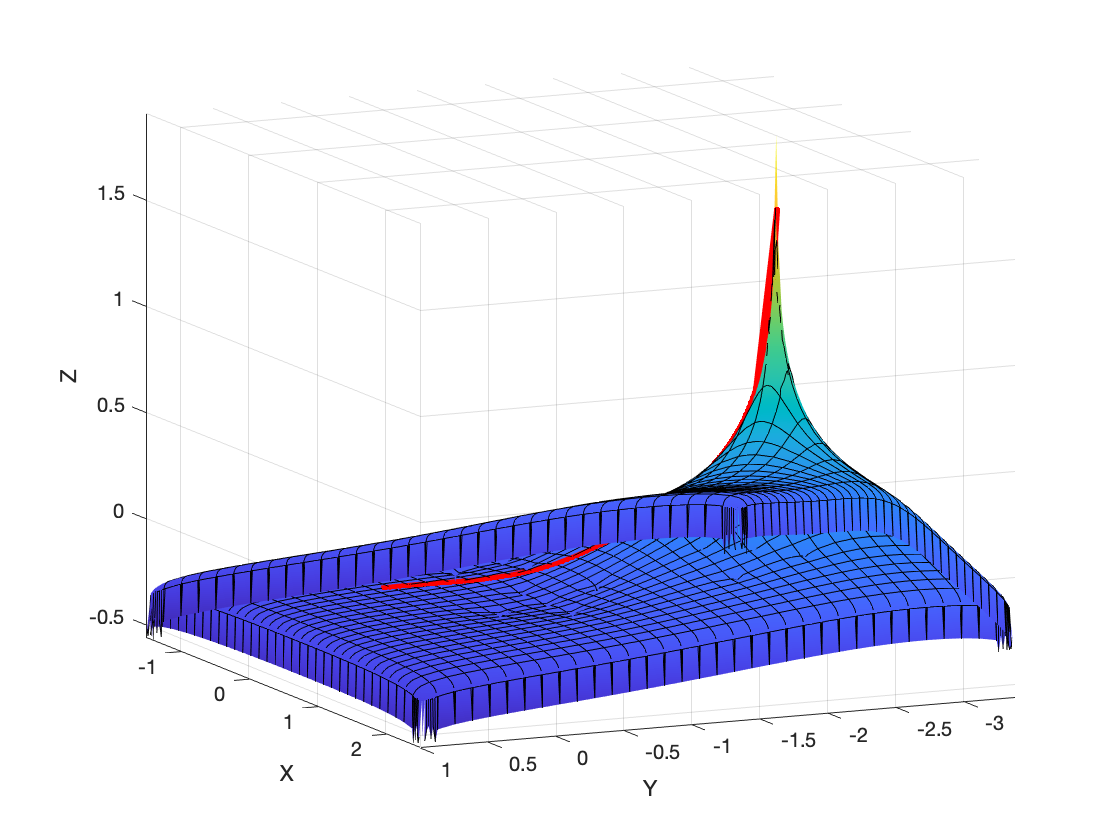

grad = matlabFunction(gradient(Z));
[positions, headings] = gradient_ascent(grad, [0, 0], [1, 0], 1, .9554, .01, 1000);
figure; clf;
fsurf(f, [-1.5, 2.5, -3.37, 1]); hold on;
plot3(positions(:, 1), positions(:, 2), f(positions(:, 1), positions(:, 2)), 'r.-', 'LineWidth', 3, "MarkerSize", 10)
xlim([-1.5, 2.5]); ylim([-3.37, 1]); xlabel("X"); ylabel("Y"); zlabel("Z");

% view([-90, 0]);
% xlim([-0.01, 0.01])

## Generate Commands for Neato

dt = 1;
d = 0.235;
ts = (1:length(positions))' .* dt;

dp = diff(positions);

angles = pi - atan2(positions(:, 2), positions(:, 1));
dangles = diff(angles)

dangles =     1.5425
   -0.0026
   -0.0032
   -0.0038
   -0.0045
   -0.0051
   -0.0057
   -0.0063
   -0.0069
   -0.0074



ang_vel = dangles ./ dt

ang_vel =     1.5425
   -0.0026
   -0.0032
   -0.0038
   -0.0045
   -0.0051
   -0.0057
   -0.0063
   -0.0069
   -0.0074



dists = vecnorm(dp, 2, 2)

dists =     0.0265
    0.0251
    0.0238
    0.0226
    0.0216
    0.0206
    0.0198
    0.0190
    0.0183
    0.0177



lin_vel = dists ./ dt

lin_vel =     0.0265
    0.0251
    0.0238
    0.0226
    0.0216
    0.0206
    0.0198
    0.0190
    0.0183
    0.0177




v_l = lin_vel + (ang_vel .* (d / 2))

v_l =     0.2078
    0.0248
    0.0234
    0.0222
    0.0211
    0.0200
    0.0191
    0.0182
    0.0175
    0.0168


v_r = lin_vel - (ang_vel .* (d / 2))

v_r =    -0.1547
    0.0254
    0.0242
    0.0231
    0.0221
    0.0212
    0.0204
    0.0197
    0.0191
    0.0185


ts = ts

ts =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


msgs = [v_l, v_r]

msgs =     0.2078   -0.1547
    0.0248    0.0254
    0.0234    0.0242
    0.0222    0.0231
    0.0211    0.0221
    0.0200    0.0212
    0.0191    0.0204
    0.0182    0.0197
    0.0175    0.0191
    0.0168    0.0185


startPos = [0, 0];
startHead = [1, 0];

save("drivedata.mat", "ts", "msgs", "startHead", "startPos");


function r_G = to_global(R, theta, origin, phi)
    [X_raw, Y_raw] = pol2cart(theta,  R);
    r_L = [X_raw, Y_raw, ones(length(X_raw), 1)]';
    r_N = [1, 0, 0.084; 0, 1, 0; 0, 0, 1] * r_L; % no rotation needed
    r_G_raw = [1, 0, origin(1); 0, 1, origin(2); 0, 0, 1] * [cos(phi), -sin(phi), 0; sin(phi), cos(phi), 0; 0, 0, 1] * r_N;
    r_G = r_G_raw(1:2, :)';
end

function r_G = plot_helper(position, results, desc)
    if nargin < 3
        desc = "Neato's View";
    end
    
    % old params: R, theta, origin, phi, desc


end